% Unidades
nm = 1E-9;
um = 1E-6;
mm = 1E-3;

% Tamaño de representación
Nx = 2048;
Ny = 2048;

% Condiciones de Muestreo
dx =6.513*mm/Nx;
dy = dx;

lambda = 633*nm;
k=(2*pi)/lambda;

distPropagacion=73*mm;

%Leer la imagen del holograma
ImHolo=imread("Hologram.tiff");%Pixeles de 2048*2048
ImHolo=imresize(ImHolo,1);
ImHolo=im2double(ImHolo);
prom = mean2(ImHolo)

prom = 0.1555

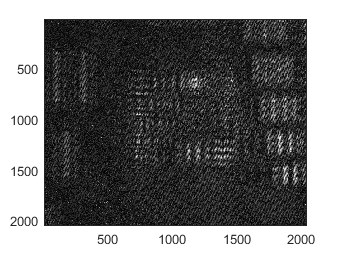

ImSinMedia = ImHolo;
imagesc(ImHolo)
colormap("gray");

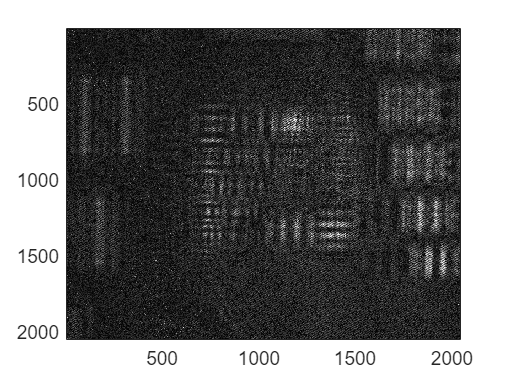

imagesc(ImSinMedia)
colormap("gray");

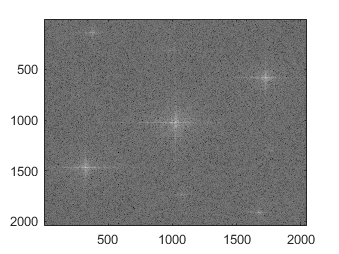




%Sacar transformada de Fourier del holograma
FourierTransform=fft2(ImHolo);
FFTHOLO = (fftshift(fft2(ImHolo)));
Transformada=imagesc(log(abs(fftshift(FourierTransform))));


% Se sacan los máximos
[maximosY,maximosX] = find(abs(FFTHOLO) == max(abs(FFTHOLO),[],"all"))

maximosY = 1025

maximosX = 1025

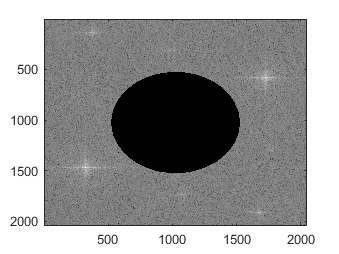


%Como el máximo central es el de mayor intensidad se elimina con un filtro
%para buscar los otros dos máximos

FFTHoloSinCentro = FFTHOLO.*(~filtroCircular([1025 1025],500,size(FFTHOLO)));
imagesc(log10(abs(FFTHoloSinCentro)))


%Deben encontrarse los dos máximos que dan cuenta de la información del
%objeto y onda de referencia

[maximosY1,maximosX1] = find(abs(FFTHoloSinCentro) == max(abs(FFTHoloSinCentro),[],"all"))

maximosY1 =         1469
         581


maximosX1 =          324
        1726


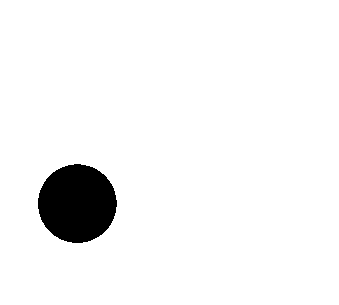


%Creación de la máscara para la selección de un orden

Mascara1= (~filtroCircular([324 1469],300,size(FFTHOLO)));
imshow(Mascara1);

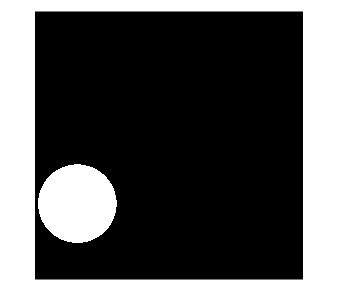

Filtro1 = imcomplement(Mascara1); 
imshow(Filtro1)

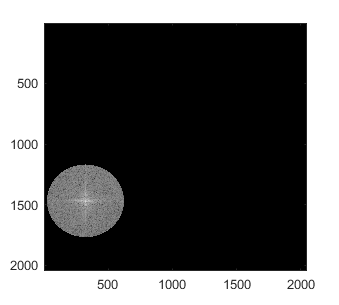



%Se multiplica la transformada por la máscara para obtener un solo orden
OrdenMas=FFTHOLO.*Filtro1;
imagesc(log(abs((OrdenMas).^2)))

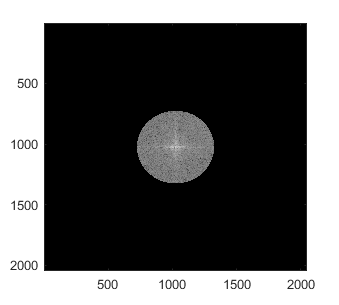

Angulos = angle(FFTHOLO);
ValorAng1 = Angulos(1469,324);
ValorAng2 = Angulos(1025,1025);
ImOrdenMas = imag(OrdenMas);
ReOrdenMas = real(OrdenMas);

angleX1=ValorAng1;
angleY1=((pi/2)-angleX1);

Onda1= plane_wave2D(Nx, Ny, angleX1, angleY1, dx, dy, k);
campoEntrada1=OrdenMas.*Onda1;

campoEntrada1 = imtranslate(campoEntrada1,[1025-324, 1025-1469],'FillValues',0);
imagesc(log(abs((campoEntrada1)).^2))


campoPrueba1 = ImHolo.*Onda1;


c1=transformadaFresnel(campoPrueba1,dx,dy,distPropagacion, lambda, "zoom", true);

%OrdenMas
ImagenFinal1=(abs((((c1))).^2));
ImagenFinal1=imresize(ImagenFinal1,2048/919)

ImagenFinal1 = 	1.0e+-29 *

    0.0012    0.0012    0.0013    0.0017    0.0024    0.0030    0.0030    0.0030    0.0045    0.0068    0.0067    0.0042    0.0022    0.0012    0.0012    0.0032    0.0054    0.0048    0.0029    0.0021    0.0023    0.0025    0.0027    0.0035    0.0055    0.0073    0.0072    0.0061    0.0056    0.0053    0.0047    0.0034    0.0036    0.0067    0.0093    0.0085    0.0066    0.0060    0.0061    0.0071    0.0090    0.0104    0.0113    0.0112    0.0088    0.0062    0.0060    0.0071    0.0067    0.0053
    0.0016    0.0017    0.0020    0.0023    0.0027    0.0030    0.0033    0.0037    0.0047    0.0060    0.0057    0.0037    0.0022    0.0016    0.0019    0.0038    0.0057    0.0053    0.0036    0.0027    0.0024    0.0027    0.0038    0.0050    0.0061    0.0068    0.0064    0.0054    0.0052    0.0053    0.0049    0.0037    0.0038    0.0067    0.0090    0.0081    0.0062    0.0055    0.0056    0.0067    0.0091    0.0105    0.0106    0.0099    0.0082    0.0064    0.0064 

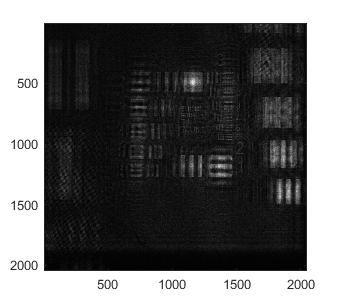

imagesc(ImagenFinal1)